## MULTI-HH TRAIN EXPERIMENT

In this notebook we will explore the training method of the multiHH class. 

**CLEANING AND FOLDERS**

%First let's clean everything and add needed folders
clc
clear
close all

addpath(genpath('extended/Domains/JSSP')); % Adds JSSP functionality
addpath(genpath('extended/Utils')); % Adds assorted utilities

**LOADING FILES**

%Loading sets of instances
load('instances_adv1.mat')
load('instances_adv2.mat')
load('instances_adv1_adv2_comb.mat')

load('FM_CHH1.mat')

**TRAINING**

Let's try with FM_CHH1 which has access to SHH5 and LPA

%setting the training instances
FM_CHH1.trainingInstances={instances_comb{[1 31 61 91]}};

%parameters of training 
properties = struct('verboseMode', true, ...
                        'maxIter', 100, 'maxStagIter', 10);

%start training                    
FM_CHH1.train('UPSO', properties)


[  07:08:37] UPSO2 starts...
         ... Inputs and outputs checked!
         ... Parameters initialised:

           visualMode: 0
          verboseMode: 1
       populationSize: 15
              maxIter: 100
          maxStagIter: 100
             selfConf: 2
           globalConf: 2.5000
          unifyFactor: 0.2500
      numberVariables: 6
    simpleConstraints: 1
             knownMin: -Inf
              stagTol: 0.1000
              funcTol: 1.0000e-03
               solTol: 1.0000e-06
         fitnessLimit: 1.0000e-06
          kappaFactor: 1
            phiFactor: 4.5000
       initialVelMode: 'rand'

         ... Neighbours established
         ... Population positions randomly initialised
         ... Population velocities randomly initialised
         ... Population initialised
         ... Search space adjusted
         ... Particular best fitness values determined

[Step     1] Global best fitness updated: 171
         ... Initialisation completed!

[Step     2] Global 

ans =     0.2186
    0.2243
    0.3648
    0.5805
    1.5097
    1.1772


The training seems to be working, as the makespan accumulate improved. It did not improved a lot but it could be due to the limitatios of the model, as it only has 2 rules and 1 features. 

%Trained model
FM_CHH1.value

ans =     0.2186    0.3648    2.0000
    0.2243    0.5805    1.0000


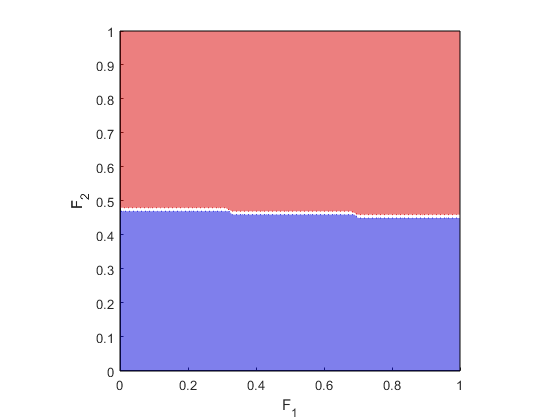

ans =     0.5299    0.4602


%Visualization of the rules
FM_CHH1.plotZones

**TRAINING A NEW CHH MODEL **

%Loadig SHHs
load('FM_SHH1.mat')
load('FM_SHH2.mat')
load('FM_SHH3.mat')
load('FM_SHH4.mat')
load('FM_SHH5.mat')

rng(1)
%Creating a new CHH model with access to SHH1-5, 5 rules and 5 features
props = struct('nbLayers',3,'selectedSolvers',1:5,...
                 'nbRules',5,'innerHHs',[FM_SHH1 FM_SHH2 FM_SHH3 FM_SHH4 FM_SHH5],'selectedFeatures', [1 2 3 4 5]);
FirstTrainedCHH=ruleBasedSelectionHHMulti(props)

FirstTrainedCHH = Warning: The hyper-heuristic has not been trained yet! 
> In selectionHH/disp (line 439)
  In matlab.internal.editor.OutputPackager.isolatedDisplaying
  In matlab.internal.editor.OutputPackager.getStringFromVar
  In matlab.internal.editor.OutputPackager.getTruncatedStringFromVar
  In matlab.internal.editor.OutputPackager/packageVarOther
  In matlab.internal.editor.OutputPackager/packageVar
  In matlab.internal.editor.OutputPackager.packageOneOutput
  In matlab.internal.editor.OutputPackager.packageOutputs
  In matlab.internal.editor.EvaluationOutputsService.outputStreamEvent
  In matlab.internal.editor.EvaluationOutputsService>@(src,ev)Ev

Let's force the model to choose all 5 SHHs 

%changing the model 
FirstTrainedCHH.value(1,end)=1;
FirstTrainedCHH.value(2,end)=2;
FirstTrainedCHH.value(3,end)=3;
FirstTrainedCHH.value(4,end)=4;
FirstTrainedCHH.value(5,end)=5

FirstTrainedCHH = Warning: The hyper-heuristic has not been trained yet! 
> In selectionHH/disp (line 439)
  In matlab.internal.editor.OutputPackager.isolatedDisplaying
  In matlab.internal.editor.OutputPackager.getStringFromVar
  In matlab.internal.editor.OutputPackager.getTruncatedStringFromVar
  In matlab.internal.editor.OutputPackager/packageVarOther
  In matlab.internal.editor.OutputPackager/packageVar
  In matlab.internal.editor.OutputPackager.packageOneOutput
  In matlab.internal.editor.OutputPackager.packageOutputs
  In matlab.internal.editor.EvaluationOutputsService.outputStreamEvent
  In matlab.internal.editor.EvaluationOutputsService>@(src,ev)Ev

Solving Instances_comb with the generated model 

%solving instances
solvedInstances_FirstTrainedCHH=FirstTrainedCHH.solveInstanceSet(instances_comb);

%Retrieving 
solvedInstances_FirstTrainedCHH_makespans=nan(length(solvedInstances_FirstTrainedCHH));


for x=1:length(solvedInstances_FirstTrainedCHH)
    solvedInstances_FirstTrainedCHH_makespans(x)=solvedInstances_FirstTrainedCHH{x}.solution.makespan;   
end
